clear all
close all

Leggo file audio

[data,Fs]=audioread('Parlato.m4a');
data=data(:,1)';

Dati

V = max(abs(data))

V = 0.6222

nbit=6

nbit = 6

M=2^nbit

M = 64

DeltaV=2*1/M

DeltaV = 0.0313

pe=1e-5

pe = 1.0000e-05

Tc = 1/Fs

Tc = 2.0833e-05

B = 1/(2*Tc)

B = 24000

mu = 255

mu = 255


data_scalato = data*(1/V);

Companding compress

data_ = compand(data_scalato, mu, max(abs(data_scalato)), 'mu/compressor');

Partizzazione uniforme

partition=[-1+DeltaV:DeltaV:1-DeltaV];
codebook=[-1+DeltaV/2:DeltaV:1-DeltaV/2];
[index,quants]=quantiz(data_,partition,codebook);

word=de2bi(index,nbit);
word_out=bsc(word,pe);

Output ed errore

index_out=bi2de(word_out);
sig_out_=codebook(index_out+1);

Copanding expand

sig_out = compand(sig_out_, mu, max(abs(data_scalato)), 'mu/expander');

Error signal

err=sig_out-data_scalato;

Grafici

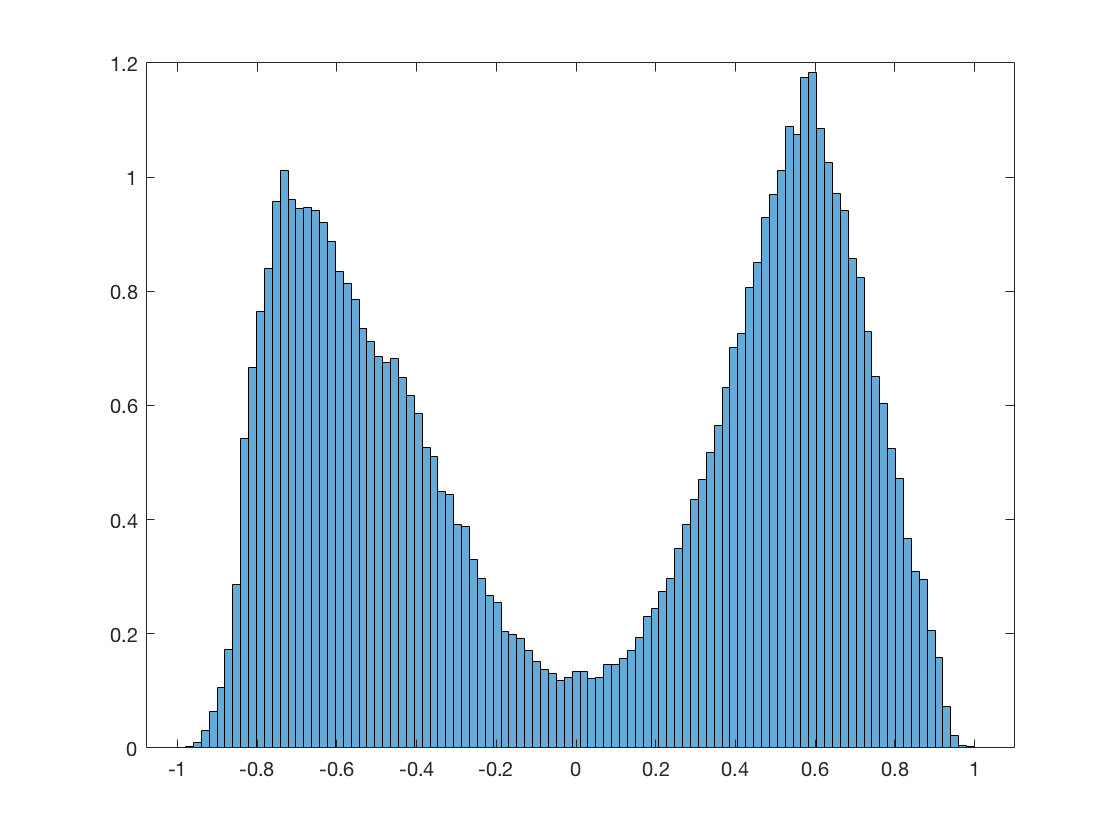

figure(1)
histogram(data_, 100, 'Normalization', 'pdf')

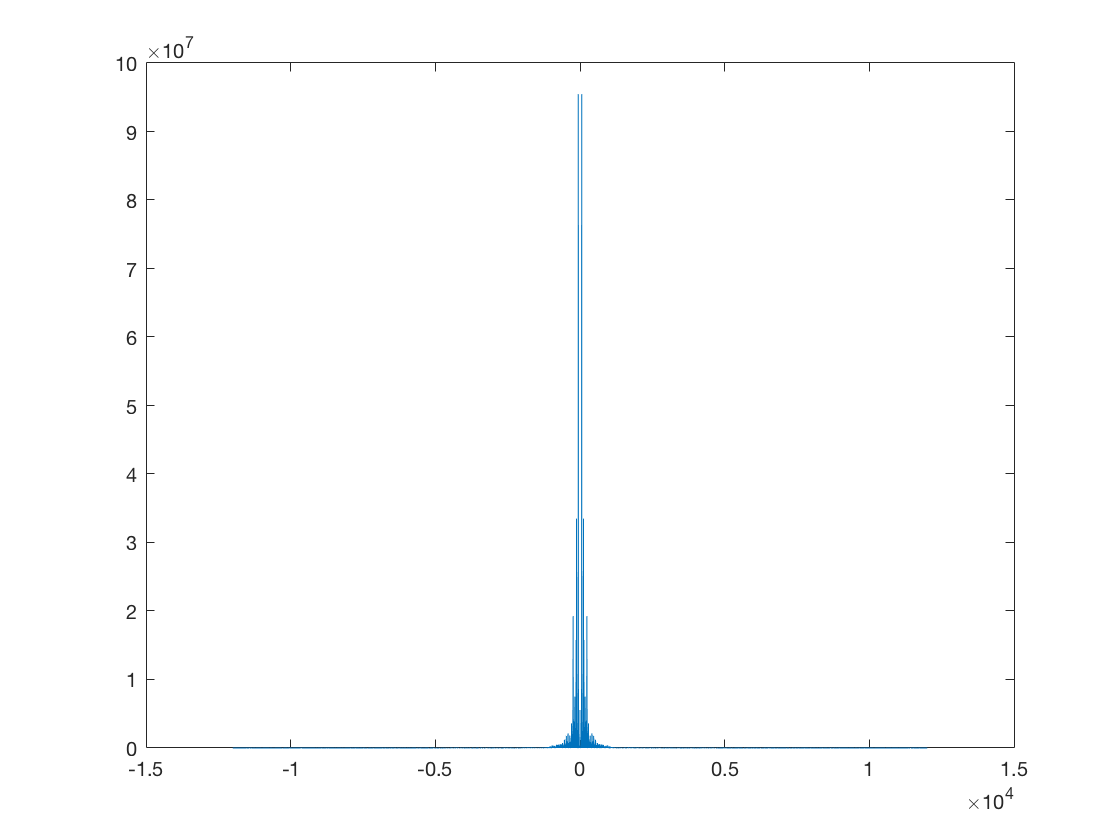


data_sp = fft(data_);
d_f = Fs/length(data_);
f = (-B/2):d_f:(B/2-d_f);
F = abs(fft(data_, length(f))).^2;
figure(2)
plot(f, fftshift(F))

Calcolo rapporto S/N teorico e pratico

N=var(err);
S=var(data_scalato);

reale = 10*log10(S/N)

reale = 25.5709


teorico_pdf_gaussiana = 10*log10((3*M^2)/(V^2)*S)

teorico_pdf_gaussiana = 29.8525


teorico_pdf_uniforme = 10*log10(M^2)

teorico_pdf_uniforme = 36.1236